## Matematično nihalo  

Cilj naloge je napisati funkcijo *nihalo*, ki izračuna gibanje matematičnega nihala podanega z diferencialno enačbo:

$\frac{g}{l}\sin \left(\theta \left(t\right)\right)+\theta \prime \prime \left(t\right)=0$,

z začetnim odmikom $\theta \left(0\right)=\theta_0$ in začetno kotno hitrostjo $\theta \prime \left(0\right)={\theta \prime }_0$. V enačbi je $g$ gravitacijski pospešek in $l$ dolžina nihala. Enačbo drugega reda smo najprej pretvorili v sistem dveh diferencialnih enačb prvega reda, kjer upeljemo $\theta \prime \left(t\right)=\;\omega$ in dobimo:


$$\begin{array}{l}
\omega \left(t\right)=\theta \prime \left(t\right)\\
\omega \prime \left(t\right)=-\frac{g}{l}\sin \left(\theta \left(t\right)\right)
\end{array}$$


Ta sistem je analitično težko rešljiv, zato za računanje uporabimo metodo Runge-Kutta reda 4. Metoda deluje iterativno, kjer računamo vrednosti funkcije na diskretnih korakih. Da dobimo naslednji približek, rešitev aproksimiramo z ovrednostenjem povprečja štirih vrednosti/naklonov znotraj enega koraka ter postopek ponavljamo. To smo zapisali v funkciji nihalo, kjer dobimo matematično pravilno gibanje nihala skozi čas.

Vseeno pa je vredno omembe, da sistem lahko analitično rešimo za majhne kote $\theta$. Za majhne kote lahko namreč $\sin \left(\theta \right)$ aproksimiramo s $\theta$, saj je funckija $\sin \left(\theta \right)$ v območju, kjer je $\theta <0\ldotp 5\;\textrm{rad}$ približno linearna. V tem primeru dobimo $\frac{d^2 \theta \;}{{\textrm{dt}}^2 }=-\frac{g}{l}\theta$ in če zapišemo $\Omega =\sqrt{\frac{g}{l}}$  dobimo splošno rešitev diferencialne enačbe za majhne kote:


$$\theta \left(t\right)=\theta_0 \;\cos \left(\Omega \;t\right)+\frac{\theta \prime_0 }{\Omega }\;\sin \left(\Omega \;t\right)$$


Opazimo lahko da je gibanje sinusoidno s periodo $T=2\pi \sqrt{\frac{l}{g}}$ , ki je neodvisna od amplitude začetnega odmika $\theta_0$. To smo ilustrirali s spodnjim grafom, kjer primerjamo matematično in harmonično nihalo. Za majhne začetne odmike se nihala gibata podobno, frekvenca nihanja (ter posledično perioda) je približno konstantna. Pri večjih kotih pa nihalo več časa "preživi" na vrhu nihanja pri največjem odmiku in njegovo gibanje ni več harmonično.

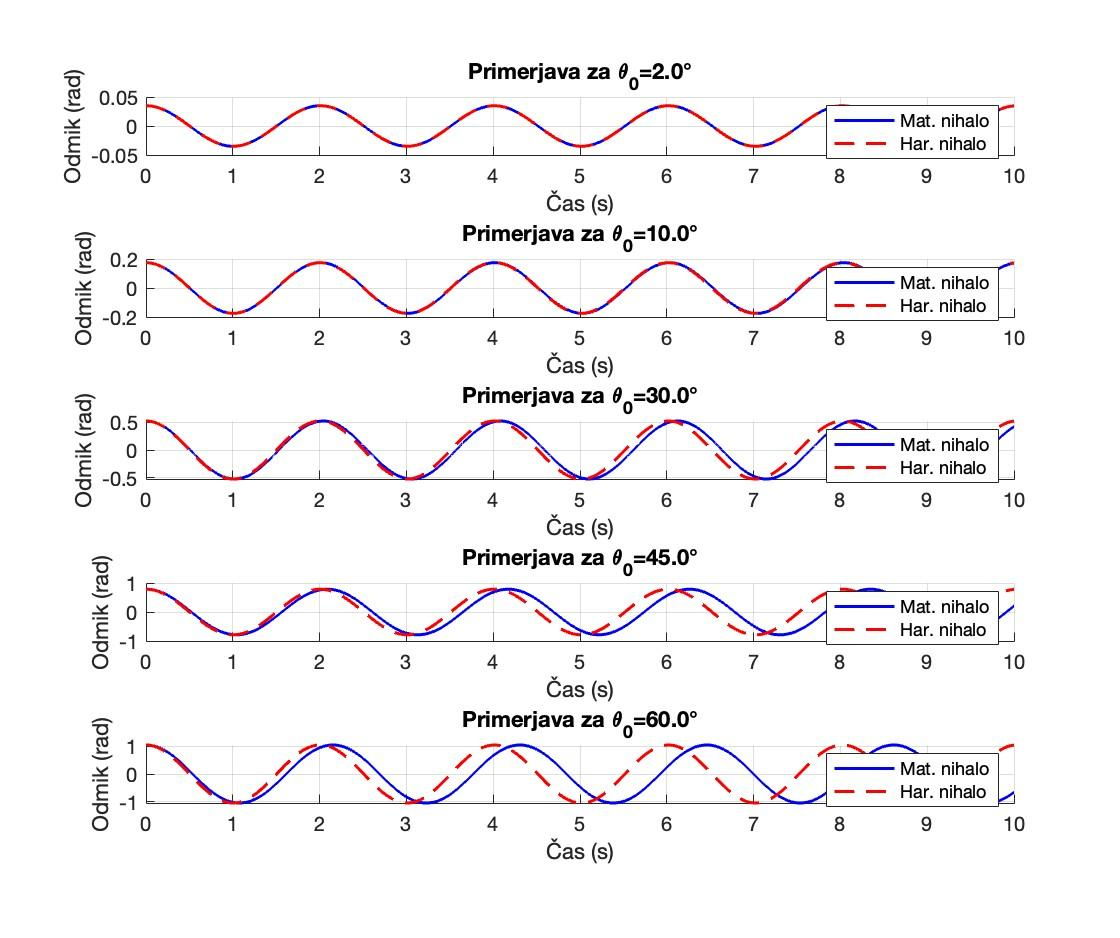

Podobni fenomen smo ilustrirali tudi z grafom, ki primerja, kako začetna hitrost $\theta \prime_0$ - torej energija vpliva na dolžino periode. Kot razvidno iz analitične rešitve je perioda harmoničnega nihala konstantna ne glede na začetno hitrost, pri matematičnem nihalu pa z začetno hitrostjo narašča. Če imamo namreč večjo začetno hitrost, se nihalo dlje zaziba in porabi več časa za en obhod. Vidimo lahko tudi, da pri večjih začetnih odmikih nihalo potrebuje manjšo začetno hitrost za enako dolg nihajni čas. Tudi to je pričakovano, saj z večjim odmikom nihalo pridobi več hitrosti in potrebujemo manj energije, da ga zazibamo.

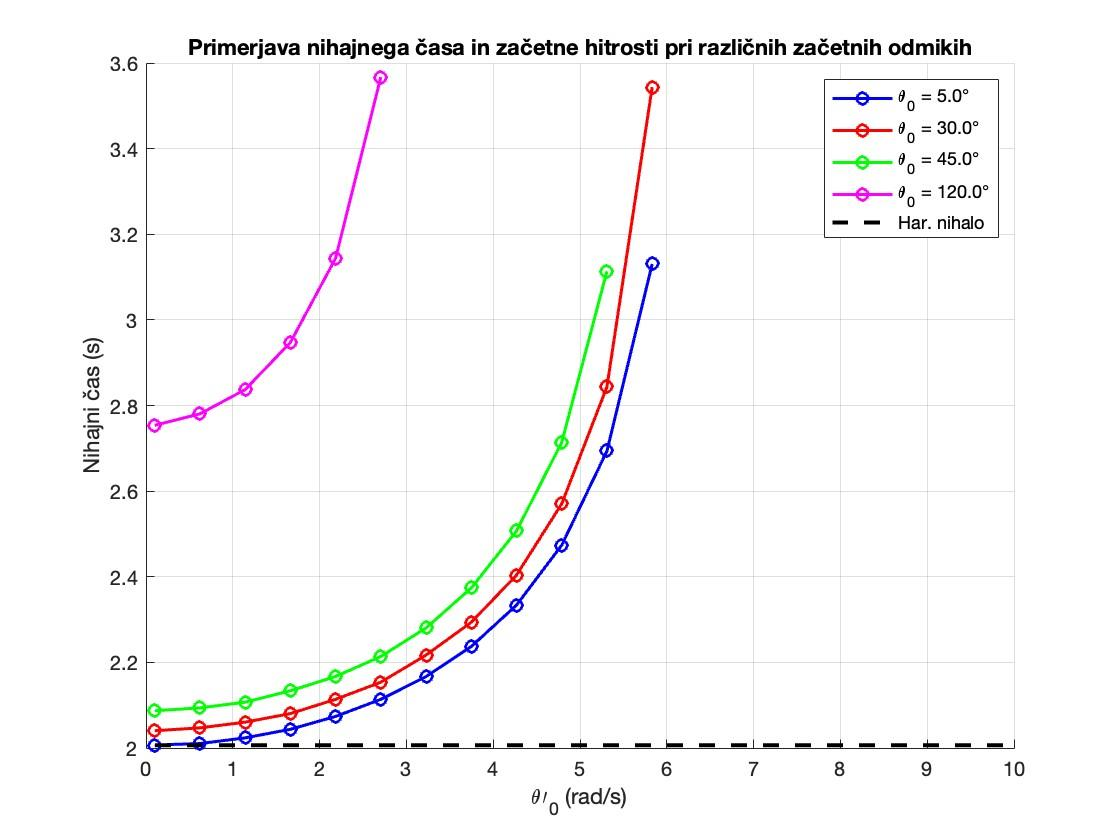

Na koncu smo izrisali še fazne diagrame matematičnega nihala za različne začetne hitrosti in začetne odmike. Na $x$ osi je prikazan odmik $\theta$, na $y$ osi pa kotna hitrost $\theta$$\prime$. Pri manjših začetnih odmikih so krivulje skoraj eliptične kar odraža harmonično nihanje, pri večjih pa lahko opazimo nelinearnost nihanja, kjer nihalo več časa ostane na robu (torej pri maksimalnem odmiku) z majhno, skoraj ničelno kotno hitrostjo.

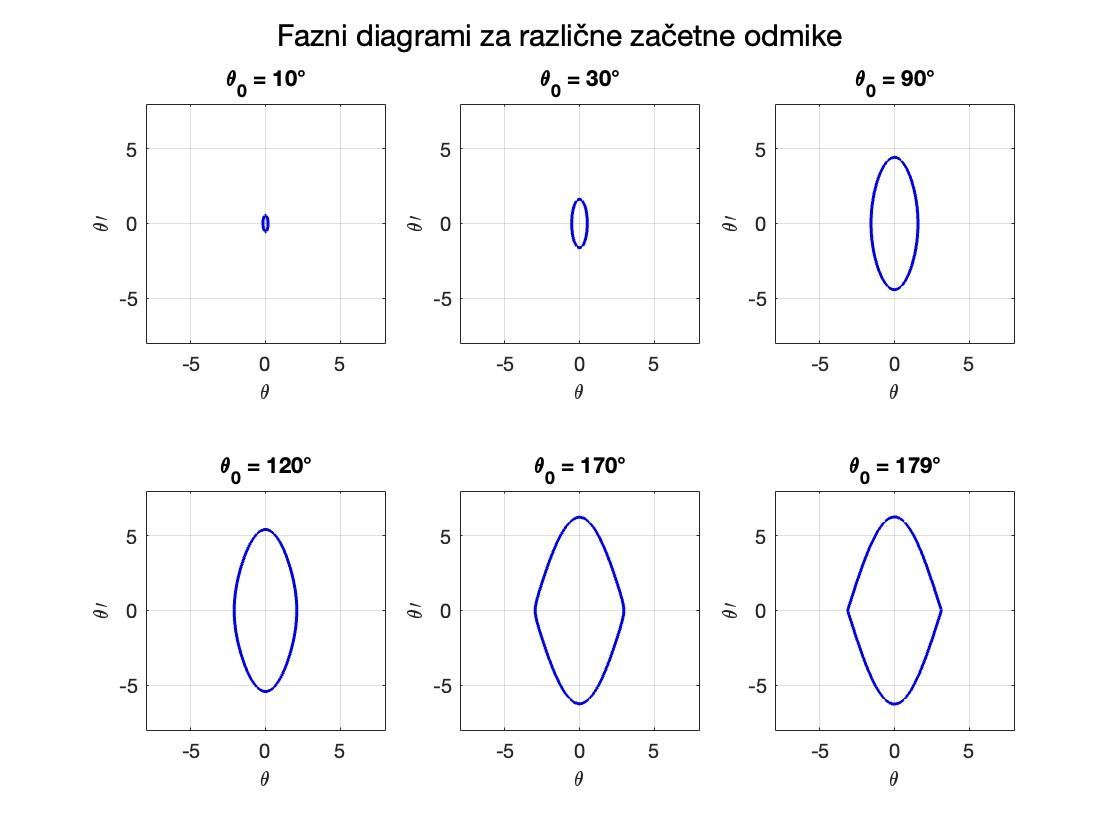

To odražajo tudi fazni diagrami za različne začetne hitrosti (izračunani z $\theta_0 =\frac{\pi }{2}$). Pri večjih začetnih hitrostih, nihalo zopet odraža nelinearno naravo sistema, saj se zaziba z večjim kotom. Pri zadnjem faznem diagramu opazimo, da je začetna hitrost tako visoka, da nihalo naredi celoten obrat; hitrost nihala se nikoli ne zmanjša na 0, odmik pa ne niha, temveč se stalno povečuje skozi čas. 

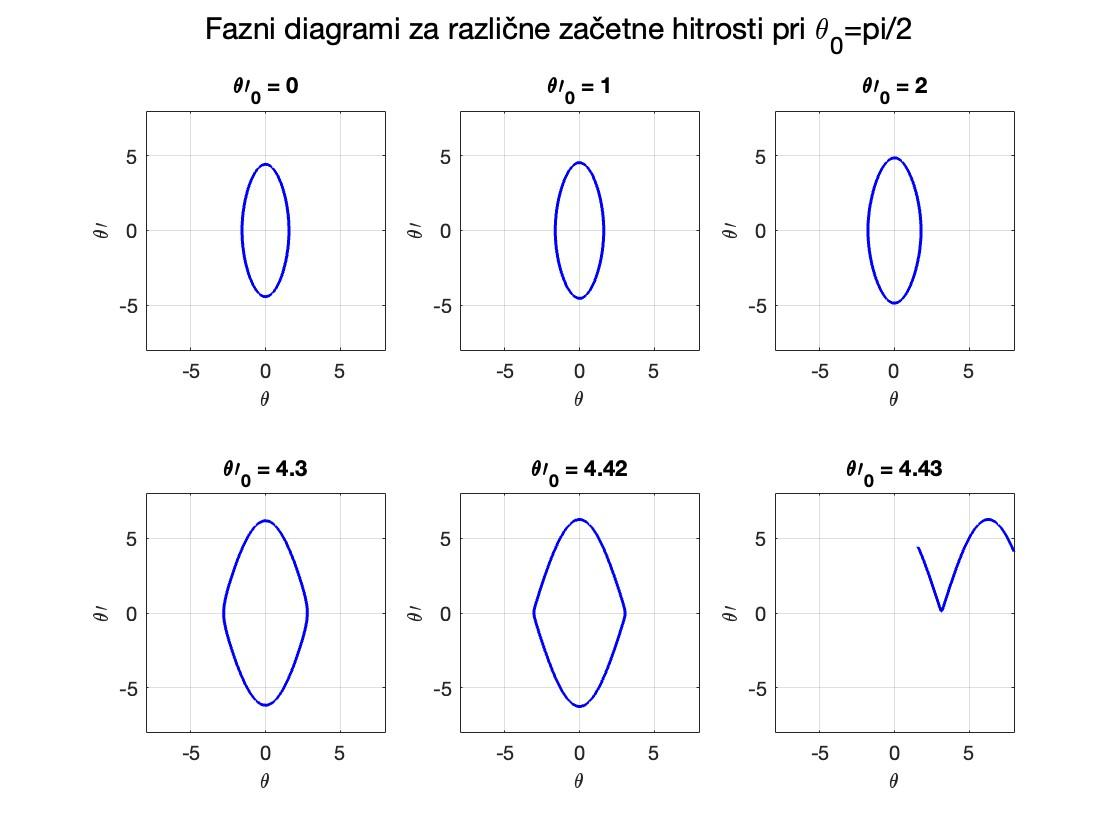

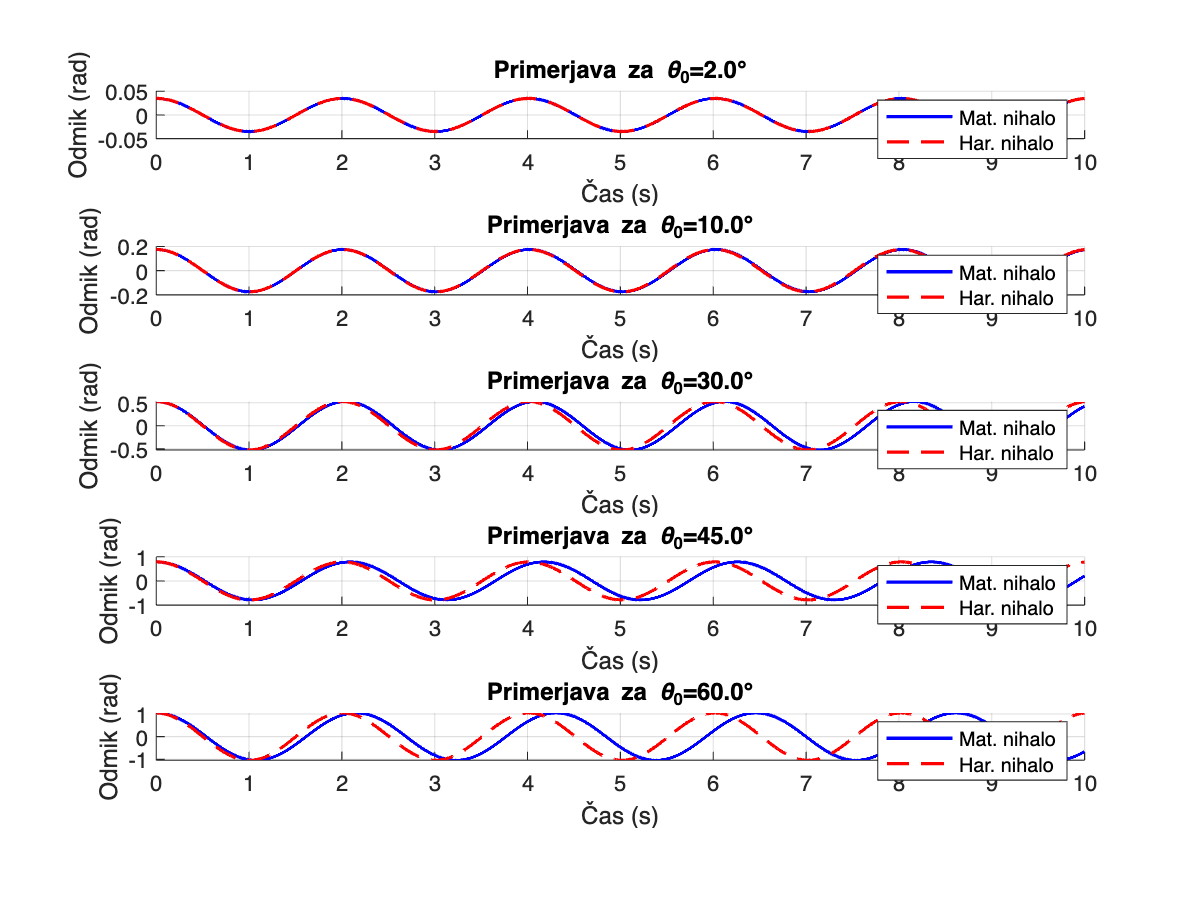

% Paramteri
l = 1;
g = 9.80665;
t = 10;
n = 6000;
time = linspace(0, t, n);


% Primerjava gibanja harmoničnega in matematičnega nihala glede na različne
% začetne odmike
theta0_values = deg2rad([2, 10, 30, 45, 60]);
compare_pendulum_harmonic([g,l,n,t], theta0_values)

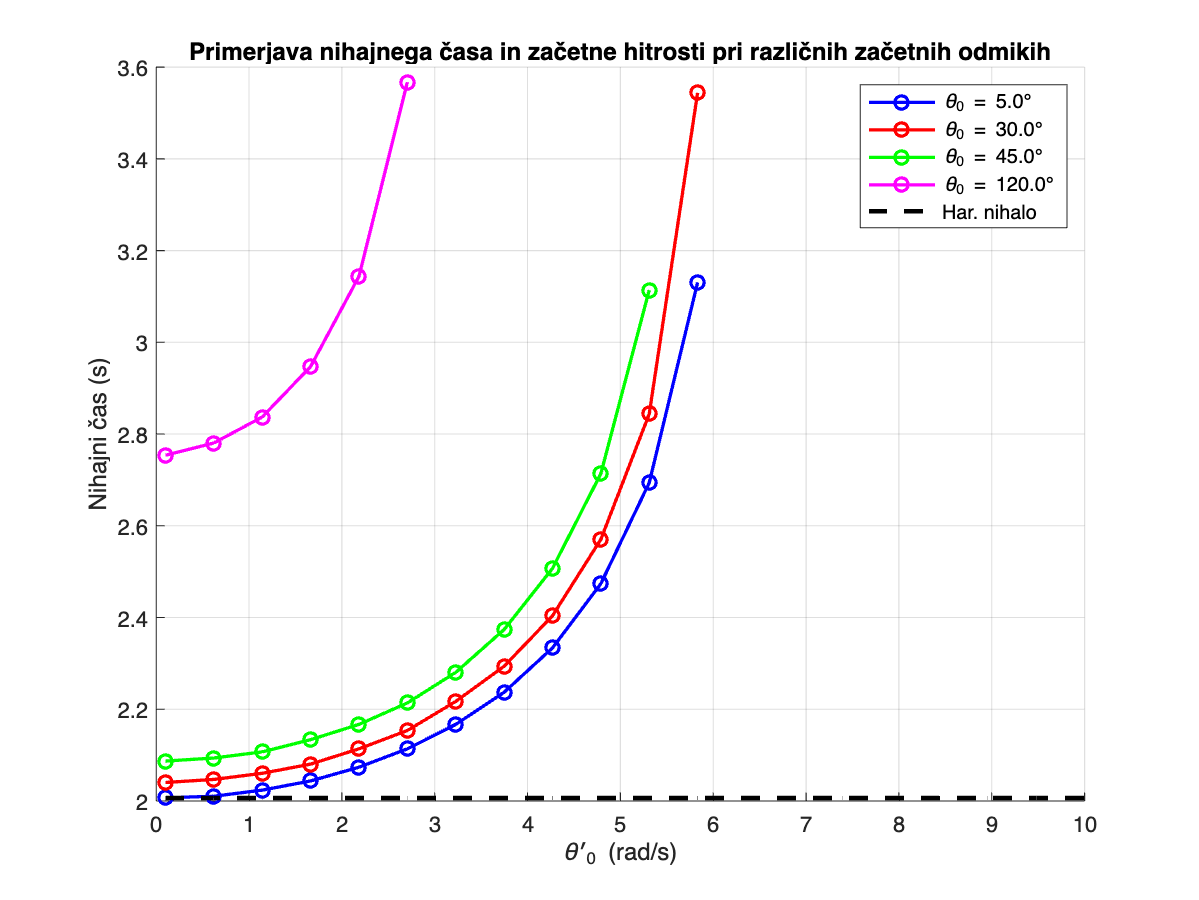

% Primerjava nihajnega časa in začetnih kotnih hitrosti
theta0_values_periods = deg2rad([5,30, 45,120]);
dtheta0_values_periods = linspace(0.1, 10, 20);
analyze_periods([g,l,n,t], theta0_values_periods, dtheta0_values_periods);

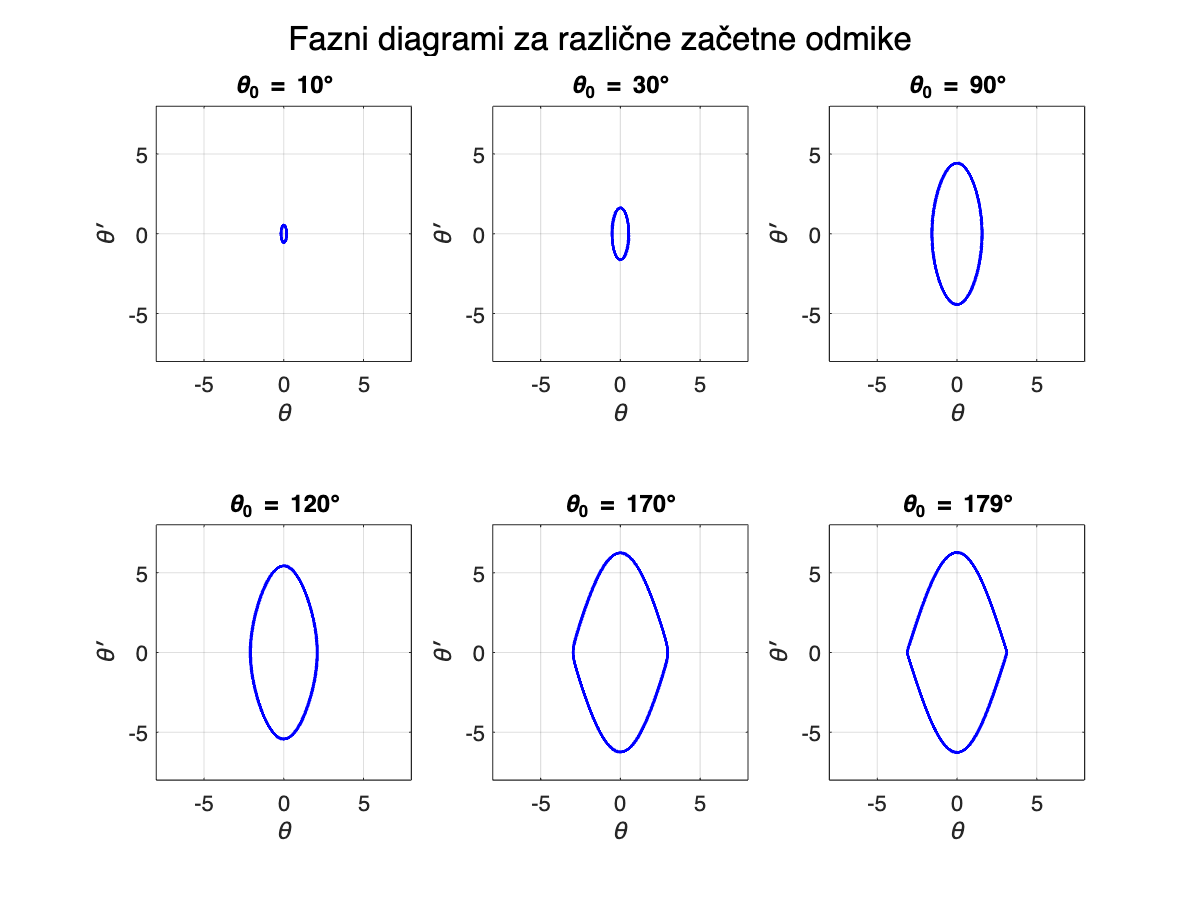

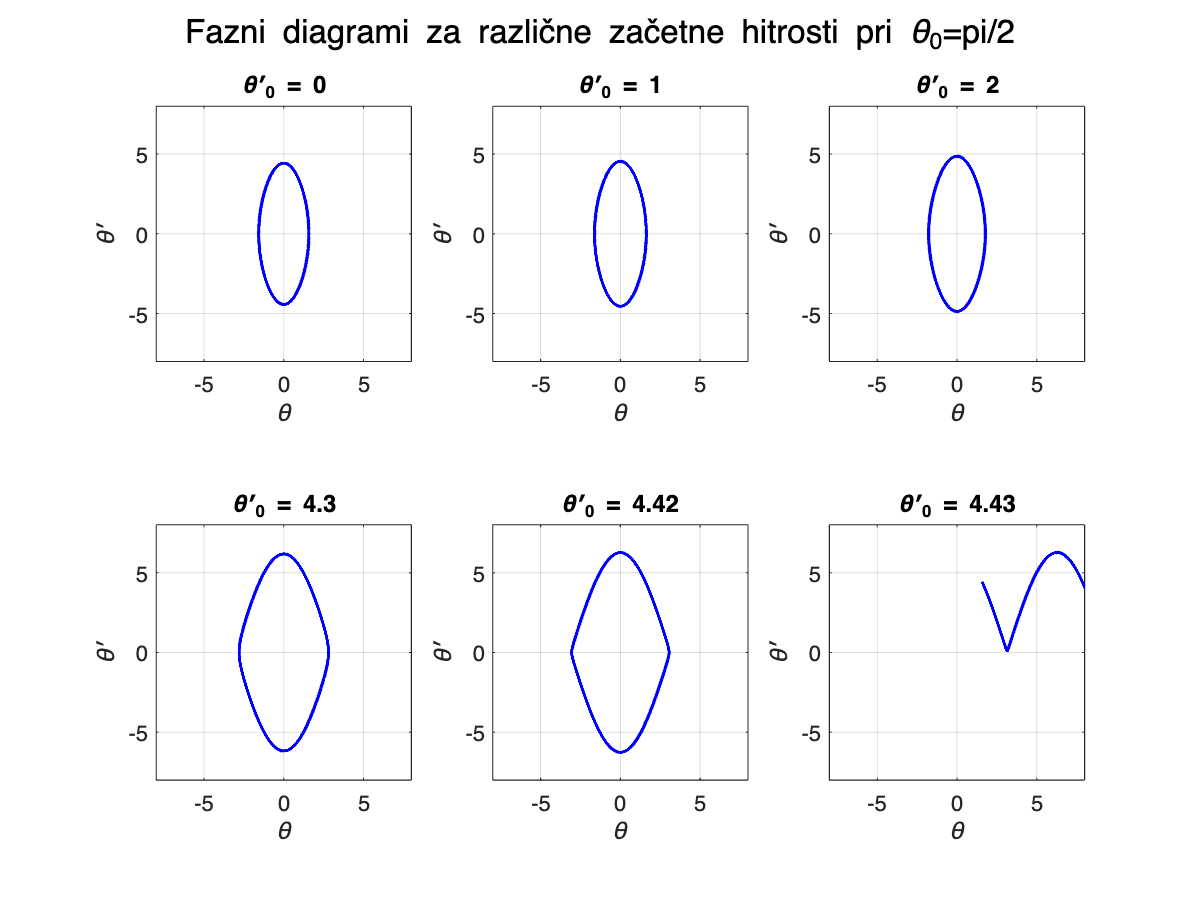

% Izris faznih diagramov za različne začetne hitrosti in odmike
theta0_values_phase = deg2rad([10, 30, 90, 120, 170, 179]);
dtheta0_values_phase = [0, 1, 2, 4.3, 4.42, 4.43];
plot_phase_diagrams([g,l,n,t], theta0_values_phase, dtheta0_values_phase);